%Setup Models variables
setupModelsVariables;

%Export Winter data with hip pose
%% Load data from xlsx file
% Swing phase 1-27
% Stance Phase 28-68
%Loading Angular Leg Kinematics
winter_data = readtable('Winter_Appendix_data.xlsx','Sheet',3, 'HeaderLines', 4);
%rel
winter_rel = readtable('Winter_Appendix_data.xlsx','Sheet',4, 'HeaderLines', 4);
t = winter_data.(3).';
%For hip-knee-ankle
for i = 1:3
    winter_theta(i,:) = winter_rel.(3*i+1).';
    winter_omega(i,:) = winter_rel.(3*i+2).';
    winter_alpha(i,:) = winter_rel.(3*i+3).';
end
% %For hat 1/2 hat segment
% winter_theta(4,:) = winter_data.(34).';
% winter_omega(4,:) = winter_data.(35).';
% winter_alpha(4,:) = winter_data.(36).';

%Loading data for hip cart. coord.
winter_hip = readtable('Winter_Appendix_data.xlsx','Sheet',2, 'HeaderLines', 4);
x_hip = winter_hip.(11).';
vx_hip = winter_hip.(12).';
ax_hip = winter_hip.(13).';
x_hip = x_hip - x_hip(1);
y_hip = winter_hip.(14).';
vy_hip = winter_hip.(15).';
ay_hip = winter_hip.(16).';
% plot(x_hip,y_hip);
%save('C:\Users\nejac\Google Drive\SU21_Collaboration\Full Gait Simscape\kinematic_data\winterKinematics.mat', 't', 'winter_theta', 'winter_omega', 'winter_alpha')

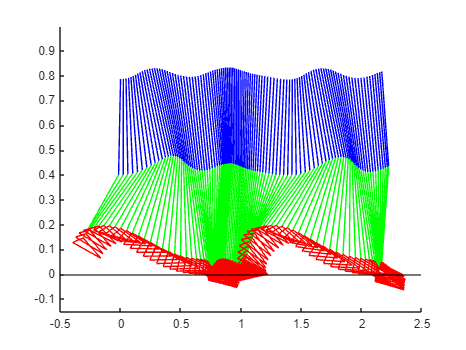

%Set var for leg kinematics
%Angles
thetaHip = winter_theta(3,:);
thetaKnee = -winter_theta(2,:)+thetaHip;
thetaAnkle = winter_theta(1,:)+thetaKnee;

%Poses
x_knee = x_hip + thighLength * sind(thetaHip);
y_knee = y_hip - thighLength * cosd(thetaHip);
x_ankle= x_knee + shankLength * sind(thetaKnee);
y_ankle= y_knee - shankLength * cosd(thetaKnee);
x_foot= x_ankle + footHeight * sind(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - winter_theta(1,:));
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - winter_theta(1,:));
x_heel= x_foot - .0204*L *sind(90 - winter_theta(1,:));
y_heel= y_foot - .0204*L *cosd(90 - winter_theta(1,:));
% hipAni = animatedline;
% kneeAni = animatedline;
% ankleAni = animatedline;
% footAni = animatedline;
% toesAni = animatedline;
% heelAni = animatedline;

figure; hold on;
yline(0,'k')

for i = 1:length(x_hip)
    plot([x_hip(i),x_knee(i)],[y_hip(i),y_knee(i)],'b');
    plot([x_knee(i),x_ankle(i)],[y_knee(i),y_ankle(i)],'g');
    plot([x_ankle(i),x_toes(i)],[y_ankle(i),y_toes(i)],'r');
    plot([x_ankle(i),x_heel(i)],[y_ankle(i),y_heel(i)],'r');
    plot([x_heel(i),x_toes(i)],[y_heel(i),y_toes(i)],'r');
    % plot([x_ankle(i),x_foot(i)],[y_ankle(i),y_foot(i)],'r');
    % plot([x_foot(i),x_toes(i)],[y_foot(i),y_toes(i)],'r');
    % plot([x_heel(i),x_foot(i)],[y_heel(i),y_foot(i)],'r');
    drawnow; %pause(.001);
    axis([-0.5 2.5 -0.15 1]);
end

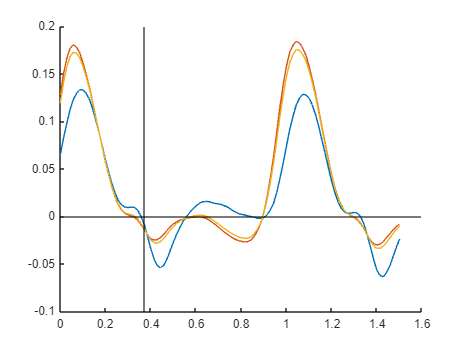


figure; hold on;
xline(t(27),'k'); yline(0,'k');
plot(t,y_toes);
plot(t,y_heel);
plot(t,y_foot);


% maxT = min(y_toes);
% maxH = min(y_heel);
% maxF = min(y_foot);


maxT = y_toes(27);
maxH = y_heel(27);
maxF = y_foot(27);

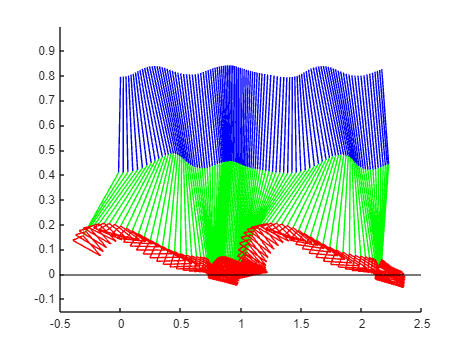

%ADJUSTED KINEMATICS STUDY
x_hip = winter_hip.(11).';
x_hip = x_hip - x_hip(1);
y_hip = winter_hip.(14).' - maxT;

%Poses
x_knee = x_hip + thighLength * sind(thetaHip);
y_knee = y_hip - thighLength * cosd(thetaHip);
x_ankle= x_knee + shankLength * sind(thetaKnee);
y_ankle= y_knee - shankLength * cosd(thetaKnee);
x_foot= x_ankle + footHeight * sind(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - winter_theta(1,:));
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - winter_theta(1,:));
x_heel= x_foot - .0204*L *sind(90 - winter_theta(1,:));
y_heel= y_foot - .0204*L *cosd(90 - winter_theta(1,:));
% hipAni = animatedline;
% kneeAni = animatedline;
% ankleAni = animatedline;
% footAni = animatedline;
% toesAni = animatedline;
% heelAni = animatedline;

figure; hold on;
yline(0,'k')

for i = 1:length(x_hip)
    plot([x_hip(i),x_knee(i)],[y_hip(i),y_knee(i)],'b');
    plot([x_knee(i),x_ankle(i)],[y_knee(i),y_ankle(i)],'g');
    plot([x_ankle(i),x_toes(i)],[y_ankle(i),y_toes(i)],'r');
    plot([x_ankle(i),x_heel(i)],[y_ankle(i),y_heel(i)],'r');
    plot([x_heel(i),x_toes(i)],[y_heel(i),y_toes(i)],'r');
    drawnow; %pause(.001);
    axis([-0.5 2.5 -0.15 1]);
end

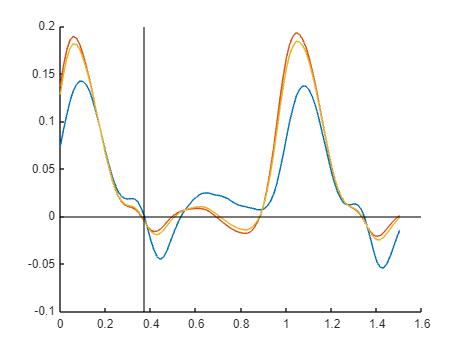


figure; hold on;
xline(t(27),'k'); yline(0,'k');
plot(t,y_toes);
plot(t,y_heel);
plot(t,y_foot);

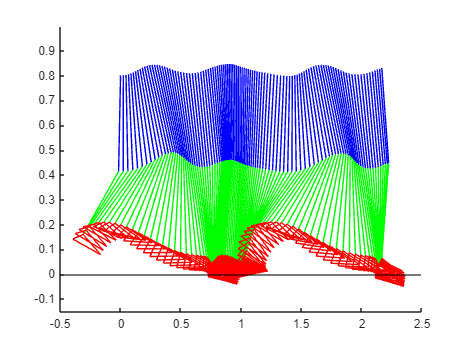

%ADJUSTED KINEMATICS STUDY
x_hip = winter_hip.(11).';
x_hip = x_hip - x_hip(1);
y_hip = winter_hip.(14).' - maxH;

%Poses
x_knee = x_hip + thighLength * sind(thetaHip);
y_knee = y_hip - thighLength * cosd(thetaHip);
x_ankle= x_knee + shankLength * sind(thetaKnee);
y_ankle= y_knee - shankLength * cosd(thetaKnee);
x_foot= x_ankle + footHeight * sind(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - winter_theta(1,:));
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - winter_theta(1,:));
x_heel= x_foot - .0204*L *sind(90 - winter_theta(1,:));
y_heel= y_foot - .0204*L *cosd(90 - winter_theta(1,:));
% hipAni = animatedline;
% kneeAni = animatedline;
% ankleAni = animatedline;
% footAni = animatedline;
% toesAni = animatedline;
% heelAni = animatedline;

figure; hold on;
yline(0,'k')

for i = 1:length(x_hip)
    plot([x_hip(i),x_knee(i)],[y_hip(i),y_knee(i)],'b');
    plot([x_knee(i),x_ankle(i)],[y_knee(i),y_ankle(i)],'g');
    plot([x_ankle(i),x_toes(i)],[y_ankle(i),y_toes(i)],'r');
    plot([x_ankle(i),x_heel(i)],[y_ankle(i),y_heel(i)],'r');
    plot([x_heel(i),x_toes(i)],[y_heel(i),y_toes(i)],'r');
    drawnow; %pause(.001);
    axis([-0.5 2.5 -0.15 1]);
end

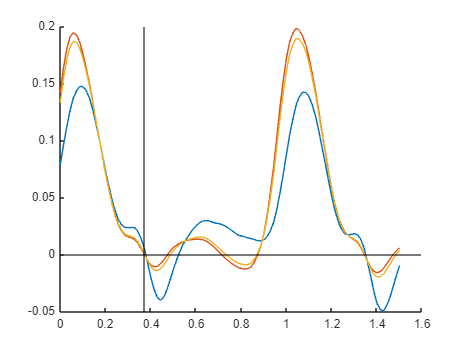


figure; hold on;
xline(t(27),'k'); yline(0,'k');
plot(t,y_toes);
plot(t,y_heel);
plot(t,y_foot);

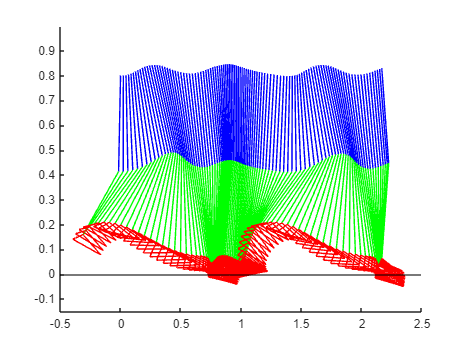

%ADJUSTED KINEMATICS STUDY
x_hip = winter_hip.(11).';
x_hip = x_hip - x_hip(1);
y_hip = winter_hip.(14).' - maxF;

%Poses
x_knee = x_hip + thighLength * sind(thetaHip);
y_knee = y_hip - thighLength * cosd(thetaHip);
x_ankle= x_knee + shankLength * sind(thetaKnee);
y_ankle= y_knee - shankLength * cosd(thetaKnee);
x_foot= x_ankle + footHeight * sind(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
y_foot= y_ankle - footHeight * cosd(thetaAnkle);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - winter_theta(1,:));
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - winter_theta(1,:));
x_heel= x_foot - .0204*L *sind(90 - winter_theta(1,:));
y_heel= y_foot - .0204*L *cosd(90 - winter_theta(1,:));
% hipAni = animatedline;
% kneeAni = animatedline;
% ankleAni = animatedline;
% footAni = animatedline;
% toesAni = animatedline;
% heelAni = animatedline;

figure; hold on;
yline(0,'k')

for i = 1:length(x_hip)
    plot([x_hip(i),x_knee(i)],[y_hip(i),y_knee(i)],'b');
    plot([x_knee(i),x_ankle(i)],[y_knee(i),y_ankle(i)],'g');
    plot([x_ankle(i),x_toes(i)],[y_ankle(i),y_toes(i)],'r');
    plot([x_ankle(i),x_heel(i)],[y_ankle(i),y_heel(i)],'r');
    plot([x_heel(i),x_toes(i)],[y_heel(i),y_toes(i)],'r');
    drawnow; %  pause(.001);
    axis([-0.5 2.5 -0.15 1]);
end

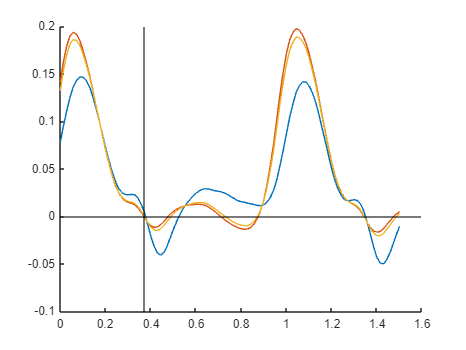


figure; hold on;
xline(t(27),'k'); yline(0,'k');
plot(t,y_toes);
plot(t,y_heel);
plot(t,y_foot);

% %Save hip kinematics
% 
% save('kinematic_data\winterHipJointKinematics.mat', 'x_hip', 'y_hip', 'vx_hip', 'vy_hip', 'ax_hip', 'ay_hip');